# Analyze the theta oscillation appeared during NW sitmulation

First, all the necessary setup

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('NtWk_Archit.mat')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.5;  
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_Drive = [60,50,42,50]*4/1e3;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3;
L6I_Drive = min(L6E_Drive);
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;

Plot Spatial maps: load data

DataFolder = [pwd '/Figures/Demo042221/'];
TPar = 10;
T_EEDly = 0.9; T_IEDly = 0.5;
% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 11:TPar+10
    text = [sprintf('DriveWkSp_TestDly_EE%.1f_IE%.1f_',T_EEDly,T_IEDly) num2str(TSec) '.mat'];
    load([DataFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end

ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
    ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
    'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(mean(lambda_E_drive)) ...
    ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
    'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];

fprintf(ParameterDisp)

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.20223, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

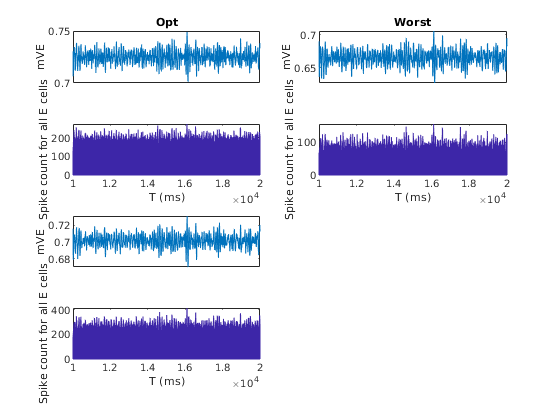


% Check soome time dependency
Opt = find(OD_E==1);
Worst = find(OD_E==3);
Nor = find(OD_E==2 | OD_E==4);

figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),Opt),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 421
plot(nanmean(mVE(OD_E'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')

subplot 424
hist(SpE(ismember(SpE(:,1),Worst),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 422
plot(nanmean(mVE(OD_E'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')

subplot 427
hist(SpE(ismember(SpE(:,1),Nor),2),T:1:T+T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
subplot 425
plot(nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')

We now focus on only one orientation domain

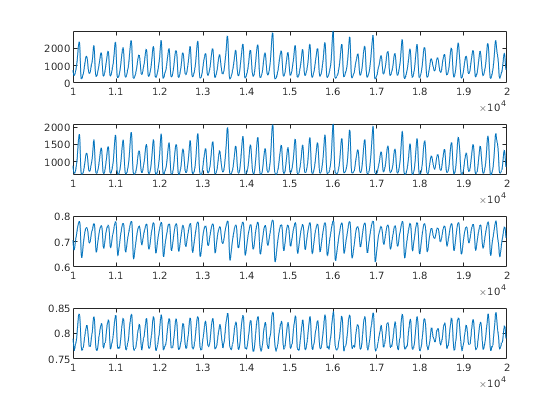

WinNum = size(mVE,2);
StatWin = linspace(T,T+TPar*1e3,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

OD_EMapTry1 = OD_EMap;
OD_EMapTry1(1:2*n_E_HC,:) = 0;
OD_EMapTry1(:,[1:n_E_HC,2*n_E_HC+1:3*n_E_HC]) = 0;
Dom1E = find(OD_EMapTry1(:)==1);
OD_IMapTry1 = OD_IMap;
OD_IMapTry1(1:2*n_I_HC,:) = 0;
OD_IMapTry1(:,[1:n_I_HC,2*n_I_HC+1:3*n_I_HC]) = 0;
Dom1I = find(OD_IMapTry1(:)==1);

Dom1Data.VE = nanmean(mVE(Dom1E,:));
Dom1Data.VI = nanmean(mVI(Dom1I,:));
Dom1Data.SpE = histcounts(SpE(ismember(SpE(:,1),Dom1E),2),StatWin);
Dom1Data.SpI = histcounts(SpI(ismember(SpI(:,1),Dom1I),2),StatWin);


OD_EMapTry2 = OD_EMap;
OD_EMapTry2(n_E_HC+1:3*n_E_HC,:) = 0;
OD_EMapTry2(:,n_E_HC+1:3*n_E_HC) = 0;
Dom2E = find(OD_EMapTry2(:)==1);
OD_IMapTry2 = OD_IMap;
OD_IMapTry2(n_I_HC+1:3*n_I_HC,:) = 0;
OD_IMapTry2(:,n_I_HC+1:3*n_I_HC) = 0;
Dom2I = find(OD_IMapTry2(:)==1);

Dom2Data.VE = nanmean(mVE(Dom2E,:));
Dom2Data.VI = nanmean(mVI(Dom2I,:));
Dom2Data.SpE = histcounts(SpE(ismember(SpE(:,1),Dom2E),2),StatWin);
Dom2Data.SpI = histcounts(SpI(ismember(SpI(:,1),Dom2I),2),StatWin);

OptE = find(OD_E==1);
OptI = find(OD_I==1);
OptData.VE = nanmean(mVE(OptE,:));
OptData.VI = nanmean(mVI(OptI,:));
OptData.SpE = histcounts(SpE(ismember(SpE(:,1),OptE),2),StatWin);
OptData.SpI = histcounts(SpI(ismember(SpI(:,1),OptI),2),StatWin);

Smth = 5;
OptData.VE = conv(OptData.VE,1/Smth*ones(1,Smth)); OptData.VE = OptData.VE(Smth:end-Smth+1);
OptData.VI = conv(OptData.VI,1/Smth*ones(1,Smth)); OptData.VI = OptData.VI(Smth:end-Smth+1);
OptData.SpE = conv(OptData.SpE,1/Smth*ones(1,Smth)); OptData.SpE = OptData.SpE(Smth:end-Smth+1);
OptData.SpI = conv(OptData.SpI,1/Smth*ones(1,Smth)); OptData.SpI = OptData.SpI(Smth:end-Smth+1);

figure("Name",'Traj on Time')
subplot 411
plot(StatWin(1:end-Smth),OptData.SpE/length(OptE)/WinSize*1e3)
title('FrE')
subplot 412
plot(StatWin(1:end-Smth),OptData.SpI/length(OptI)/WinSize*1e3)
title('FrI')
subplot 413
plot(StatWin(1:end-Smth),OptData.VE)
title('mVE')
subplot 414
plot(StatWin(1:end-Smth),OptData.VI)

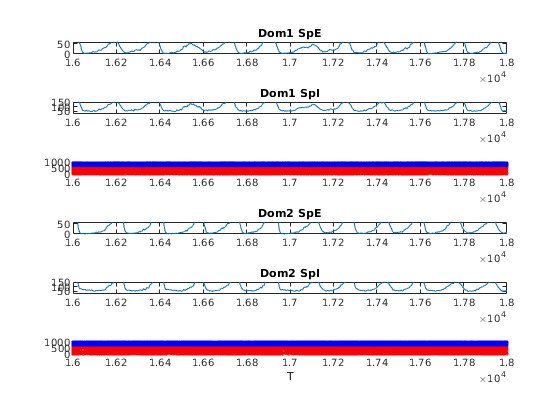

title('mVI')

figure("Name",'DiffDom')
subplot 611
plot(StatWin(1:end-1),Dom1Data.SpE/length(Dom1E)/WinSize*1e3)
title('Dom1 SpE');ylim([0 90]);xlim([16000 18000])
subplot 612
plot(StatWin(1:end-1),Dom1Data.SpI/length(Dom1I)/WinSize*1e3)
title('Dom1 SpI');ylim([20 220]);xlim([16000 18000])
subplot 613
hold on
SpETime = SpE(ismember(SpE(:,1),Dom1E),2);
SpENInd = SpE(ismember(SpE(:,1),Dom1E),1);
[DomSrN, ~] = sort(Dom1E);
for SpInd = 1:length(SpENInd)
    SpENInd(SpInd) = find(DomSrN == SpENInd(SpInd));
end
SpITime = SpI(ismember(SpI(:,1),Dom1I),2);
SpINInd = SpI(ismember(SpI(:,1),Dom1I),1);
[DomSrN, ~] = sort(Dom1I);
for SpInd = 1:length(SpINInd)
    SpINInd(SpInd) = find(DomSrN == SpINInd(SpInd));
end
scatter(SpETime, SpENInd ,'r.')
scatter(SpITime, SpINInd+max(SpENInd) ,'b.')
xlim([16000 18000])

subplot 614
plot(StatWin(1:end-1),Dom2Data.SpE/length(Dom2E)/WinSize*1e3)
title('Dom2 SpE');ylim([0 90]);xlim([16000 18000])
subplot 615
plot(StatWin(1:end-1),Dom2Data.SpI/length(Dom2I)/WinSize*1e3)
title('Dom2 SpI');ylim([20 220]);xlim([16000 18000])
subplot 616
hold on
SpETime = SpE(ismember(SpE(:,1),Dom2E),2);
SpENInd = SpE(ismember(SpE(:,1),Dom2E),1);
[DomSrN, ~] = sort(Dom2E);
for SpInd = 1:length(SpENInd)
    SpENInd(SpInd) = find(DomSrN == SpENInd(SpInd));
end
SpITime = SpI(ismember(SpI(:,1),Dom2I),2);
SpINInd = SpI(ismember(SpI(:,1),Dom2I),1);
[DomSrN, ~] = sort(Dom2I);
for SpInd = 1:length(SpINInd)
    SpINInd(SpInd) = find(DomSrN == SpINInd(SpInd));
end
scatter(SpETime, SpENInd ,'r.')
scatter(SpITime, SpINInd+max(SpENInd) ,'b.')
xlim([16000 18000])

xlabel('T')

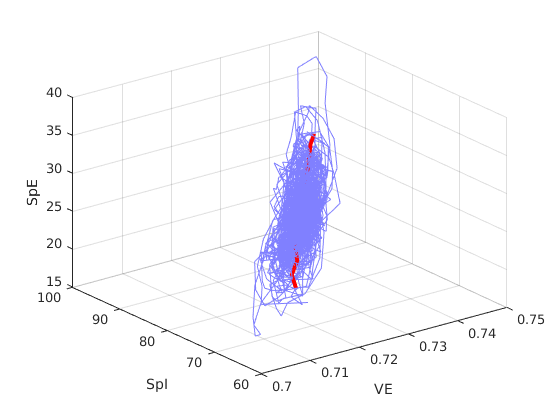

figure("Name",'Traj on Time gif')
plot3(OptData.VE,OptData.VI/length(OptI)/WinSize*1e3,...
                  OptData.SpE/length(OptE)/WinSize*1e3,'Color',[0.5,0.5,1],'LineWidth',0.2)
xlabel('VE');ylabel('VI');zlabel('SpE')
grid on
SamSize = 10;
hold on

for tInd = 1:length(OptData.SpE) - SamSize
    tempwin = tInd:tInd+SamSize;
    tempobj = plot3(OptData.VE(tempwin),OptData.VI(tempwin)/length(OptI)/WinSize*1e3,...
                                         OptData.SpE(tempwin)/length(OptE)/WinSize*1e3,'r','LineWidth',3);
    drawnow
    pause(0.2)
    delete(tempobj)
end